%Maths week 4 tutorial sheet
%product rule example f

%1)
syms ya(x) yb(x) yc(x) yd(t) ye(x) yf(x)

%differentiating each question to validate pen and paper results
ya(x) = x^5;
diff(ya,x);
simplify(ans)

$$ans(x) = 5\,x^{4}$$


yb(x) = sqrt(x);
diff(yb,x);
simplify(ans)

$$ans(x) = \frac{1}{2\,\sqrt{x}}$$


yc(x) = (1/x^3);
diff(yc,x);
simplify(ans)

$$ans(x) = -\frac{3}{x^{4}}$$


yd(x) = cos(3*t);
diff(yd,t);
simplify(ans)

$$ans(x) = -3\,\sin\left(3\,t\right)$$


ye(x) = log(2.5*x);
diff(ye,x);
simplify(ans)

$$ans(x) = \frac{1}{x}$$


yf(x) = exp(-2*x);
diff(yf,x);
simplify(ans)

$$ans(x) = -2\,{\mathrm{e}}^{-2\,x}$$

%2)
syms ya(x) yb(x) yc(x) solc(x) yd(x) sold(x) ye(t) yf(t) solf(t) yg(x) yh(x)

%differentiating each question to validate pen and paper results
ya(x) = 2*sin(4*x);
diff(ya,x);
simplify(ans)

$$ans(x) = 8\,\cos\left(4\,x\right)$$


yb(x) = 2*x^3 + 5*x^2 -3*x +6;
diff(yb,x);
simplify(ans)

$$ans(x) = 6\,x^{2}+10\,x-3$$


yc(x) = (2/x) - (5/x^2);
diff(yc,x);
simplify(ans)

$$ans(x) = -\frac{2\,\left(x-5\right)}{x^{3}}$$

solc(x) = 10/x^3 - 2/x^2 %declaring pen & paper solution

$$solc(x) = \frac{10}{x^{3}}-\frac{2}{x^{2}}$$

isAlways(solc == ans) %checking if pen & paper solution matches matlab answer

ans = logical
   1



yd(x) = sqrt(x) + 1/sqrt(x)

$$yd(x) = \frac{1}{\sqrt{x}}+\sqrt{x}$$

diff(yd,x);
simplify(ans)

$$ans(x) = \frac{x-1}{2\,x^{3/2}}$$

sold(x) = 1/(2*sqrt(x)) - 1/(2*sqrt(x^3));
simplify(sold)

$$ans(x) = \frac{1}{2\,\sqrt{x}}-\frac{1}{2\,\sqrt{x^{3}}}$$

isAlways(sold == ans)

ans = logical
   1


ye(x) = t*exp(-2*t);
diff(ye,t);
simplify(ans)

$$ans(x) = -{\mathrm{e}}^{-2\,t}\,\left(2\,t-1\right)$$


yf(t) = sin(t)*exp(-t);
solf(t) = exp(-t)*(-cos(t) - sin(t));
diff(yf,t);
simplify(ans - solf)

$$ans(t) = 2\,{\mathrm{e}}^{-t}\,\cos\left(t\right)$$

isAlways(ans == solf)

ans = logical
   0


%not getting matching solutions

yg(x) = (x^-2)*cos(x);
diff(yg,x);
simplify(ans)

$$ans(x) = -\frac{2\,\cos\left(x\right)+x\,\sin\left(x\right)}{x^{3}}$$


yh(x) = sin(x^2 + 1);
diff(yh,x);
simplify(ans)

$$ans(x) = 2\,x\,\cos\left(x^{2}+1\right)$$

%3)
syms y_a(x) y_b(x) y_c(t) y_d(w) y_e(x) y_f(x) ome phy y_g(x) y_h(x) y_i(t);

y_a(x) = 9*x^4 - 5*x^3 +4*x;
diff(y_a,x)

$$ans(x) = 36\,x^{3}-15\,x^{2}+4$$


y_b(x) = 1/(x+3);
diff(y_b,x)

$$ans(x) = -\frac{1}{{\left(x+3\right)}^{2}}$$


y_c(t) = sqrt(t+4);
diff(y_c,t)

$$ans(t) = \frac{1}{2\,\sqrt{t+4}}$$


y_d(w) = 1/(sqrt(w-2));
diff(y_d,w)

$$ans(w) = -\frac{1}{2\,{\left(w-2\right)}^{3/2}}$$


y_e(x) = 5*x^4 + 3*x + 1;
diff(y_e,x);
diff(ans,x)

$$ans(x) = 60\,x^{2}$$


y_f(x) = sin(ome*x + phy)^2;
diff(y_f,x)

$$ans(x) = 2\,\mathrm{ome}\,\cos\left(\mathrm{phy}+\mathrm{ome}\,x\right)\,\sin\left(\mathrm{phy}+\mathrm{ome}\,x\right)$$


y_g(x) = 3^(2*x);
diff(y_g,x)

$$ans(x) = 2\,3^{2\,x}\,\log\left(3\right)$$


y_h(x) = exp(x^2);
diff(y_h,x)

$$ans(x) = 2\,x\,{\mathrm{e}}^{x^{2}}$$


y_i(t) = log(9*t^2);
diff(y_i,t)

$$ans(t) = \frac{2}{t}$$

%4)
syms y(x);
y(x) = (x+1)*exp(-2*x);
diff(y,x);
simplify(ans)

$$ans(x) = -{\mathrm{e}}^{-2\,x}\,\left(2\,x+1\right)$$

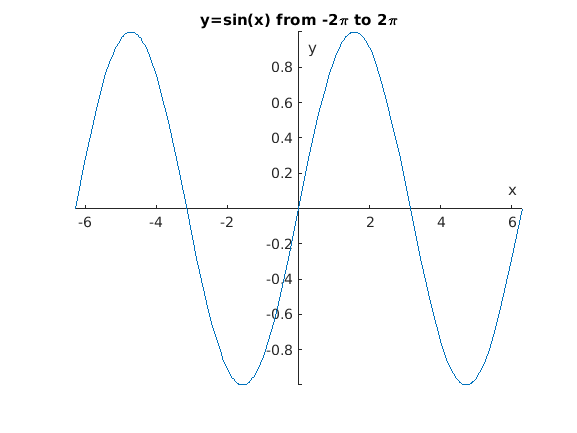

%5)
syms y(x);

y(x) = sin(x); %declaring function

%plotting function
fplot(y, [-2*pi 2*pi])

%beaeutifying
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;
xlabel("x");
ylabel("y");
title("y=sin(x) from -2\pi to 2\pi");